# Tutorial 10 - A P2D Model of an LNMO-Graphite Cell

## Introduction

In this tutorial, we will build, run, and visualize a pseudo-two-dimensional (P2D) simulation for a Li-ion battery cell with an LNMO positive electrode and a graphite negative electrode. In the process, we will get more experience with how to define **BattMo** models from multiple parameter sources and explore the details of the simulation output.

## Define Parameters

**BattMo** uses JSON to manage parameters. This allows you to easily save, document, and share complete parameter sets from specific simulations. We have used long and explicit key names for good readability. If you are new to JSON, you can learn more about it [here](https://www.w3schools.com/js/js_json_intro.asp). Details on the BattMo specification are available in the [JSON input specification](http://json.html/#json-input-specification).

First, we load and parse the JSON input file describing the basic LNMO-Graphite electrochemical cell definiton into **BattMo** using the command:

jsonfilename = fullfile('ParameterData', 'BatteryCellParameters', 'LithiumIonBatteryCell', ...
                        'lithium_ion_battery_lnmo_graphite.json');
jsonstruct_material = parseBattmoJson(jsonfilename);

Running a simulation in BattMo also requires information about the geometry of the battery cell and the control protocol to be used. To help with mixing and matching model definitions, we recommend to maintain these descriptions as separate files and merge them together to create a simulation. For example, we can add a geometry definition and control protocol using the following commands:

% Geometry
jsonfilename = fullfile('Examples', 'JsonDataFiles', 'geometry1d.json');
jsonstruct_geometry = parseBattmoJson(jsonfilename);
jsonstruct_geometry.Geometry.faceArea = 0.01;

% Control
jsonfilename = fullfile('Examples', 'JsonDataFiles', 'cc_discharge_control.json');
jsonstruct_control = parseBattmoJson(jsonfilename);
jsonstruct_control.Control.lowerCutoffVoltage = 3.5;

Now we can merge the json structures into one model definition:

jsonstruct = mergeJsonStructs({jsonstruct_geometry , ...
                               jsonstruct_material , ...
                               jsonstruct_control  
                              });

This transforms the parameter data as a [MATLAB structure](https://se.mathworks.com/help/matlab/structures.html) `jsonstruct` that is used to setup the simulation. We can explore the structure within the MATLAB Command Window by navigating the different levels of the structure.

disp(jsonstruct)

                      Geometry: [1×1 struct]
             NegativeElectrode: [1×1 struct]
             PositiveElectrode: [1×1 struct]
                     Separator: [1×1 struct]
                             G: []
                           SOC: 0.9900
                         initT: 298.1500
                   use_thermal: 1
    include_current_collectors: 0
                   Electrolyte: [1×1 struct]
                  ThermalModel: [1×1 struct]
                       Control: [1×1 struct]



We can see that the structure contains various attributes for the different aspects of the model. For example, if we want to know the thickness of the negative electrode coating, we can navigate the hierarchy to find it:

disp(jsonstruct.NegativeElectrode.Coating.thickness)

   6.4000e-05



Unless otherwise specified, BattMo uses [SI base units](https://www.nist.gov/si-redefinition/definitions-si-base-units) for physical quantities.

## Run Simulation

We can run the simulation with the command:

output = runBatteryJson(jsonstruct);

Solving timestep 001/100:                                            -> 50 Seconds, 399 Milliseconds
Solving timestep 002/100: 50 Seconds, 399 Milliseconds               -> 100 Seconds, 799 Milliseconds
Solving timestep 003/100: 100 Seconds, 799 Milliseconds              -> 151 Seconds, 199 Milliseconds
Solving timestep 004/100: 151 Seconds, 199 Milliseconds              -> 201 Seconds, 599 Milliseconds
Solving timestep 005/100: 201 Seconds, 599 Milliseconds              -> 252 Seconds
Solving timestep 006/100: 252 Seconds                                -> 302 Seconds, 399 Milliseconds
Solving timestep 007/100: 302 Seconds, 399 Milliseconds              -> 352 Seconds, 799 Milliseconds
Solving timestep 008/100: 352 Seconds, 799 Milliseconds              -> 403 Seconds, 199 Milliseconds
Solving timestep 009/100: 403 Seconds, 199 Milliseconds              -> 453 Seconds, 599 Milliseconds
Solving timestep 010/100: 453 Seconds, 599 Milliseconds              -> 503 Seconds, 999 Milliseconds

## Show the Dashboard

We can dashboard the main results using [plotDashboard](https://github.com/BattMoTeam/BattMo/blob/main/Utilities/Visualization/plotDashboard.m). Here, for example at time step 10,

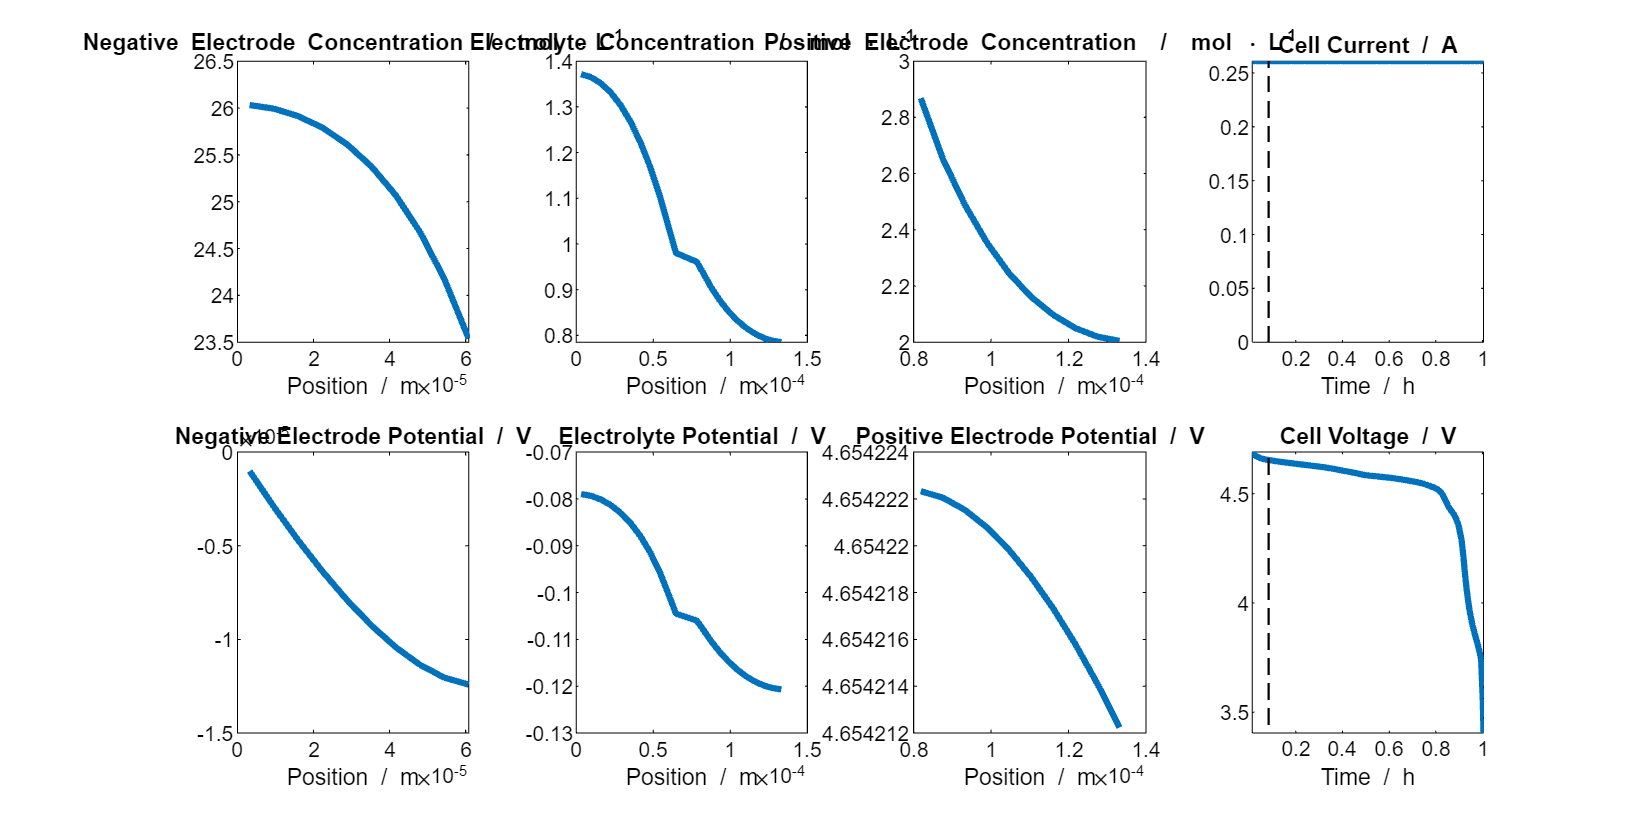

plotDashboard(output.model, output.states, 'step', 10);

The left 3 columns of the dashboard shows the profiles for the main state quantities (concentration and electric potential) in the negative electrode, electrolyte, and positive electrode. The rightmost column shows the calculated cell current and voltage. In the following subsections, we will explore how to access and plot this data from the simulation output.

## Explore the Output

The `output` structure returns among other thing the model and the states.

disp(output)

          model: [1×1 Battery]
    inputparams: [1×1 BatteryInputParams]
       schedule: [1×1 struct]
      initstate: [1×1 struct]
           time: [87×1 double]
              E: [87×1 double]
              I: [87×1 double]
         states: {87×1 cell}



The `model` contains information about the setup of the model and initial conditions, while `states` contains the results of the simulation at each timestep. Plotting the simulation results requires information about the grid (i.e. what is the position where the quantity is calculated?) and the state (i.e. what is the value of the quantity in that position at a given time?).

## Explore the Grid

The grid (or mesh) is one of the most used properties of the model, which can be accessed with the command:

disp(output.model.grid)

      cells: [1×1 struct]
      faces: [1×1 struct]
      nodes: [1×1 struct]
    griddim: 1
       type: 'generic'



We can see that the grid is stored as a structure with information about the cells, faces, nodes, etc. The values of the state quantities (e.g. concentration and electric potential) are calculated at the centroids of the cells. To plot the positions of the centroids, we can use the following commands:

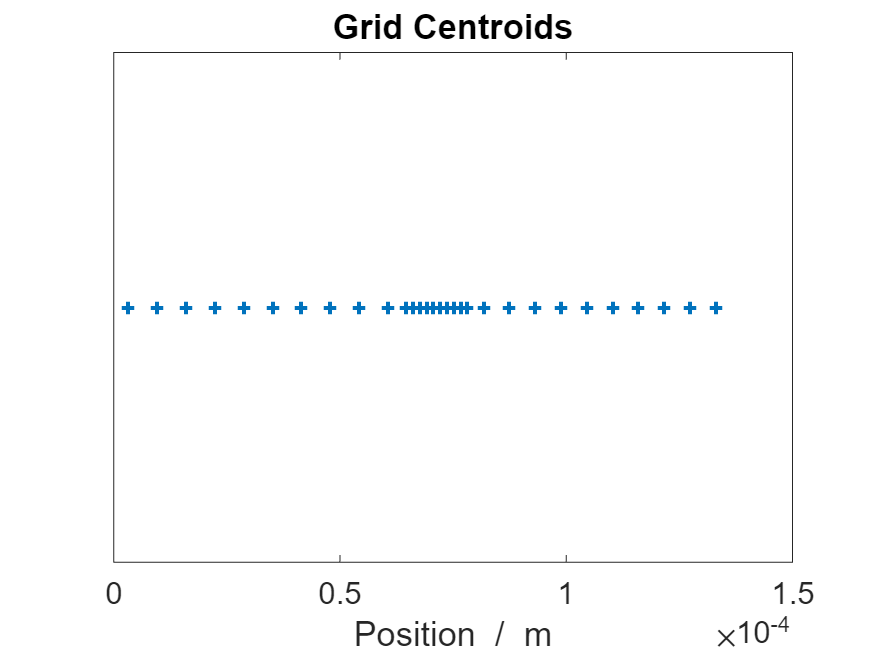

% get the centroid locations for the full grid
x = output.model.grid.cells.centroids;

% plot them in a figure
figure();
grid_axes = axes();
plot(grid_axes, x, zeros(size(x)), '+', 'LineWidth', 2)

% remove the y-axis ticks
yticks([]);

% add plot annotations
title('Grid Centroids');
xlabel('Position  /  m');

This shows the overall grid that is used for the model. However, **BattMo** models use a modular hierarchy where the overall cell model is composed of smaller submodels for electrodes, electrolyte, and current collectors. Each of these submodels has its own grid.

For example, if we want to plot the grid associated with the different submodels in different colors, we can use the following commands:

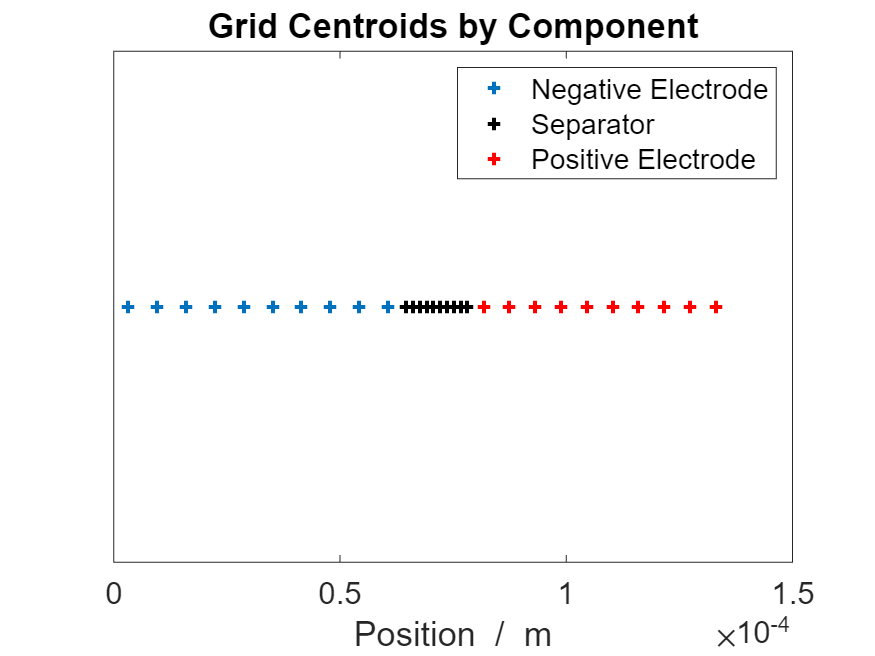

% get the centroid locations for the negative electrode (x_ne), separator
% (x_sep), and positive electrode (x_pe)
x_ne = output.model.NegativeElectrode.grid.cells.centroids;
x_sep = output.model.Separator.grid.cells.centroids;
x_pe = output.model.PositiveElectrode.grid.cells.centroids;

% plot them together on one figure
figure()
plot(x_ne, zeros(size(x_ne)), '+', 'LineWidth', 2)
hold on
plot(x_sep, zeros(size(x_sep)), '+k', 'LineWidth', 2)
plot(x_pe, zeros(size(x_pe)), '+r', 'LineWidth', 2)

% remove the y-axis tick marks
yticks([]);

% add plot annotations
title('Grid Centroids by Component')
xlabel('Position  /  m')
legend('Negative Electrode', 'Separator', 'Positive Electrode')

If you would like more information about the **BattMo** model hierarchy, please see [BattMo Model Architecture](http://architecture.html/#battmo-model-architecture).

## Explore the States

The values of the state quantities at each time step are stored in the `states` [cell array](https://se.mathworks.com/help/matlab/cell-arrays.html). Each entry in the array describes the state of the simulation at a given timestep.

For example, we can look at the state of the simulation at timestep 10 (shown in the dashboard plot above) using the command:

timestep = 10;
disp(output.states{timestep})

          Electrolyte: [1×1 struct]
    NegativeElectrode: [1×1 struct]
    PositiveElectrode: [1×1 struct]
         ThermalModel: [1×1 struct]
              Control: [1×1 struct]
                 time: 302.4000



We see that the time of the state is 504 seconds and there are other structures containing the states of the electrodes and electrolyte. We can look into the state of the electrolyte using the command:

disp(output.states{timestep}.Electrolyte)

      c: [30×1 double]
    phi: [30×1 double]



which shows that there are two quantities there for concentration, c, and electric potential, phi.

## Plot a Result

Let’s plot the concentration in the electrolyte at timestep 10. We can plot the results using basic MATLAB commands this way:

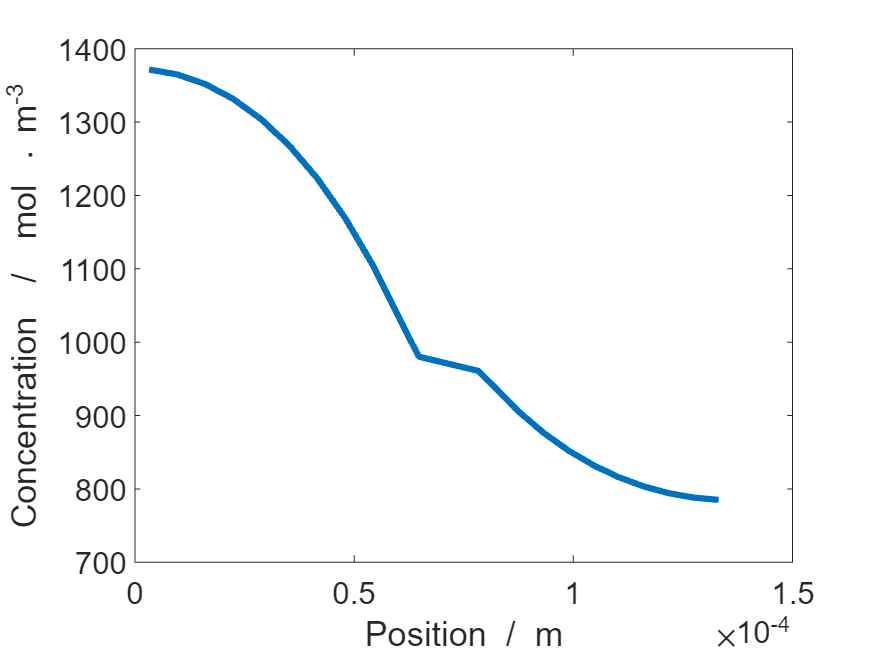

% get the centroid locations and the values for the electrolyte
% concentration at the given timestep
x = output.model.grid.cells.centroids;
c = output.states{timestep}.Electrolyte.c;

% plot the concentration values at the given grid centroid locations
figure()
plot(x, c, 'LineWidth', 3)

% add plot annotations
xlabel('Position  /  m')
ylabel('Concentration  /  mol \cdot m^{-3}')

We can also view the same data as a single contour plot projected through time.

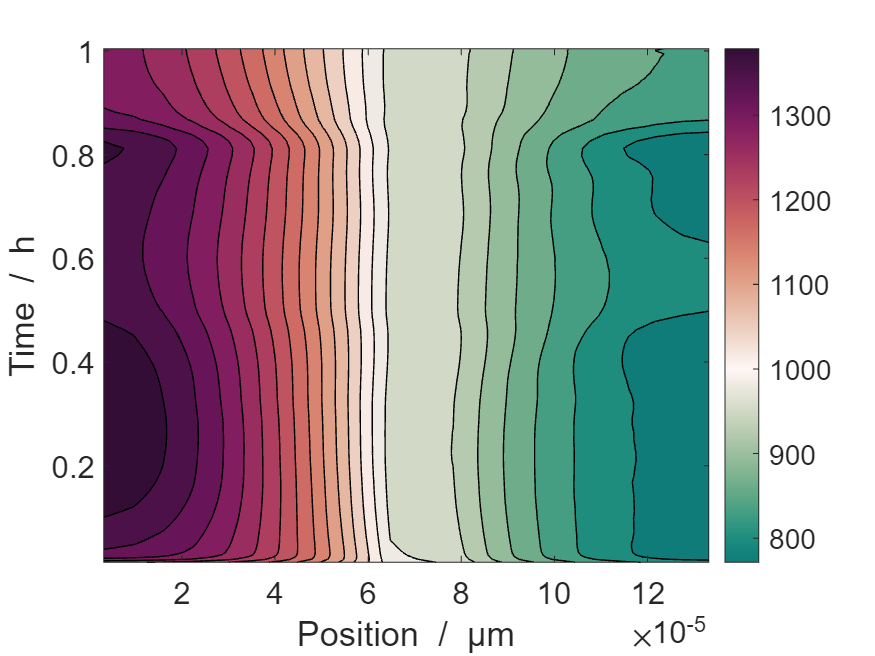

states = output.states;
time = output.time;
% instantiate matrices
numStates = numel(states);
maxSize = max(cellfun(@(x) numel(x.Electrolyte.c), output.states));
c_elyte = NaN(numStates, maxSize);

% Loop through each element in 'states' and extract 'c' values
for i = 1:numStates
    c_elyte(i, 1:numel(output.states{i}.Electrolyte.c)) = output.states{i}.Electrolyte.c;
end

% plot the concentration values over space (x axis) and time (y axis)
h = figure();
contourf(x, time/hour, c_elyte, 20, 'LineWidth',0.1)
cm = cmocean('curl', 'pivot', 1000);
colormap(cm)
xlabel('Position  /  µm')
ylabel('Time  /  h')
colorbar()

You did it! You have run an post-processed your first BattMo simulation! But there are still a lot of exciting features to discover. Let’s keep going and explore making chages to the model.